% Task 3
Fs = 8192;
f = 1000;
n = [1:8192];
x = sin(2*pi*n*f/Fs);
spectrogram(x, 256, [], [], Fs, 'yaxis')
soundsc(x,Fs);

pause(2);

f = 2000;
x = sin(2*pi*n*f/Fs);
spectrogram(x, 256, [], [], Fs, 'yaxis')
soundsc(x,Fs);

pause(2);

f = 3000;
x = sin(2*pi*n*f/Fs);
spectrogram(x, 256, [], [], Fs, 'yaxis')
soundsc(x,Fs);

pause(2);

% Nyquist frequency is Fs/2 i.e, 8192/2 = 4096

f = 6000;
x = sin(2*pi*n*f/Fs);
spectrogram(x, 256, [], [], Fs, 'yaxis')
soundsc(x,Fs);

pause(2);

f = 7000;
x = sin(2*pi*n*f/Fs);
spectrogram(x, 256, [], [], Fs, 'yaxis')
soundsc(x,Fs);

pause(2);

f = 8000;
x = sin(2*pi*n*f/Fs);
spectrogram(x, 256, [], [], Fs, 'yaxis')
soundsc(x,Fs);


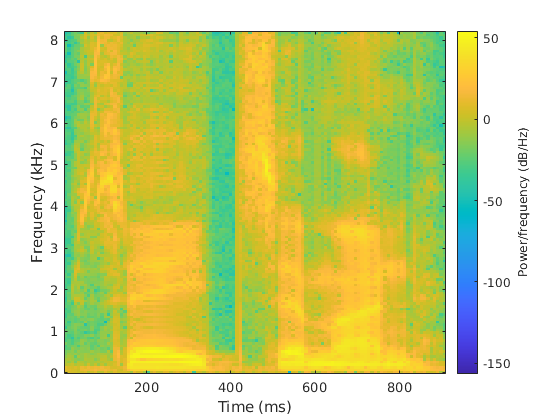


% Task 4
clear all;
load seiska.mat;
Fs=16384;
spectrogram(x, 256, [], [], Fs, 'yaxis');

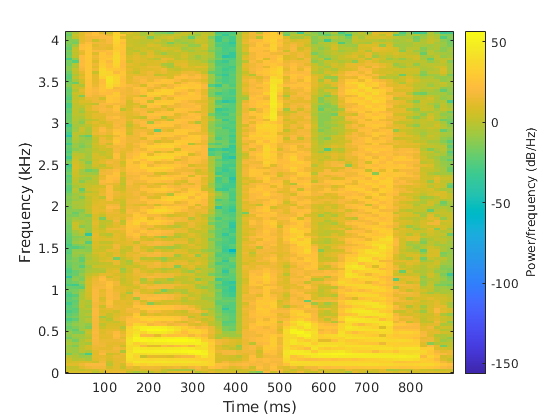

soundsc(x,Fs);

pause(2)

y=x(1:2:length(x));
Fs= Fs/2;
spectrogram(y, 256, [], [], Fs, 'yaxis');

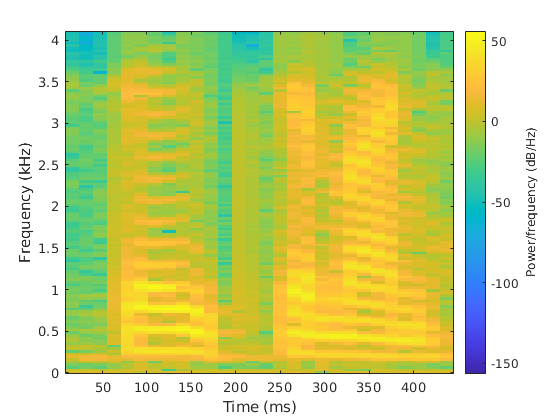

soundsc(y,Fs);

pause(2)

z=decimate(x,4);
spectrogram(z, 256, [], [], Fs, 'yaxis');

soundsc(z,Fs);

% Task 5 - a
clear all
load gong.mat;
soundsc(y,Fs);
subplot(2,1,1);
spectrogram(y,256, [], [], Fs, 'yaxis');
pause(4);
h=[-0.2427 -0.2001 0.7794 -0.2001 -0.2427];
z=conv(h,y);
soundsc(z,Fs);
subplot(2,1,2);
spectrogram(z,256, [], [], Fs, 'yaxis');

% lower frequencies from 0 - 0.5 khz are removed in filtered signal

% Task 5 - b
clear all
[h,Fs] = audioread('hall.wav');
soundsc(h, Fs);
pause(2);
load seiska.mat
soundsc(x, Fs);
pause(2);
z = conv(h, x);

z = 	1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0009   -0.0007   -0.0009   -0.0008   -0.0005   -0.0007   -0.0007   -0.0005


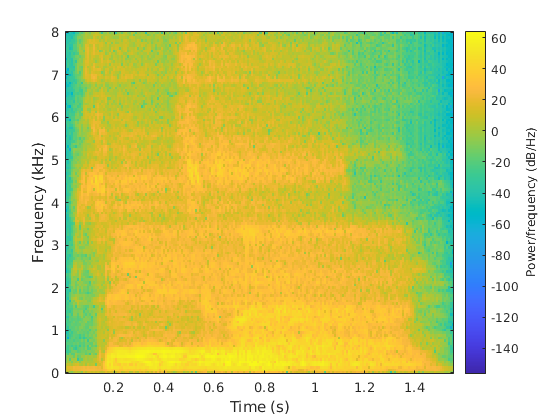

soundsc(z,Fs);
spectrogram(z,256, [], [], Fs, 'yaxis');